# Universidad de Guadalajara

## CUCEI

## Visión Robótica

## **Proyecto Final**

# Detección de esquinas y bordes en imagenes en Matlab

## ***Angel José Avila Trasviña***

## ***Luis Angel Muñoz Franco***

***Introducción***

Al considerarse el caso de un robot que cuenta con una cámara para detectar lo que tiene enfrente de él y un sensor ultrasonico para medir la distancia hacia ese objeto, se procede a implementar una serie de algoritmos y programas que le permitan al robot conocer los limites de estos objetos que encontrará en su camino; estos limites vendrán dados por los bordes del objeto y las esquinas.

El procesamiento en tiempo real de imagenes cuentra con la severa desventaja del tiempo computacional necesario para realizar estas tareas de procesamiento de imagenes, tomando esto en cuenta se procede a hacer lo siguiente buscando el mejor desempeño posible:

- Conversión a escala de grises

- Aplicación de filtro promedio

- Encoger la imagen a 1/4 de su tamaño original

- Aplicación de HDR

- Aplicamos filtro mediana para prevenir ruido

- Detectar marcos de los objetos con el algoritmo Canny

- Aplicar Closing y Opening a la imagen

- Detección de objeto y esquinas con Harris

- Devolver las mejores posiciones donde hay un objeto

## ***Desarrollo***

Para esta presentación solo consideraremos una imagen, pero el mismo resultado puede ser utilizado para una serie de imagenes o un video.

Primero leemos la imagen:

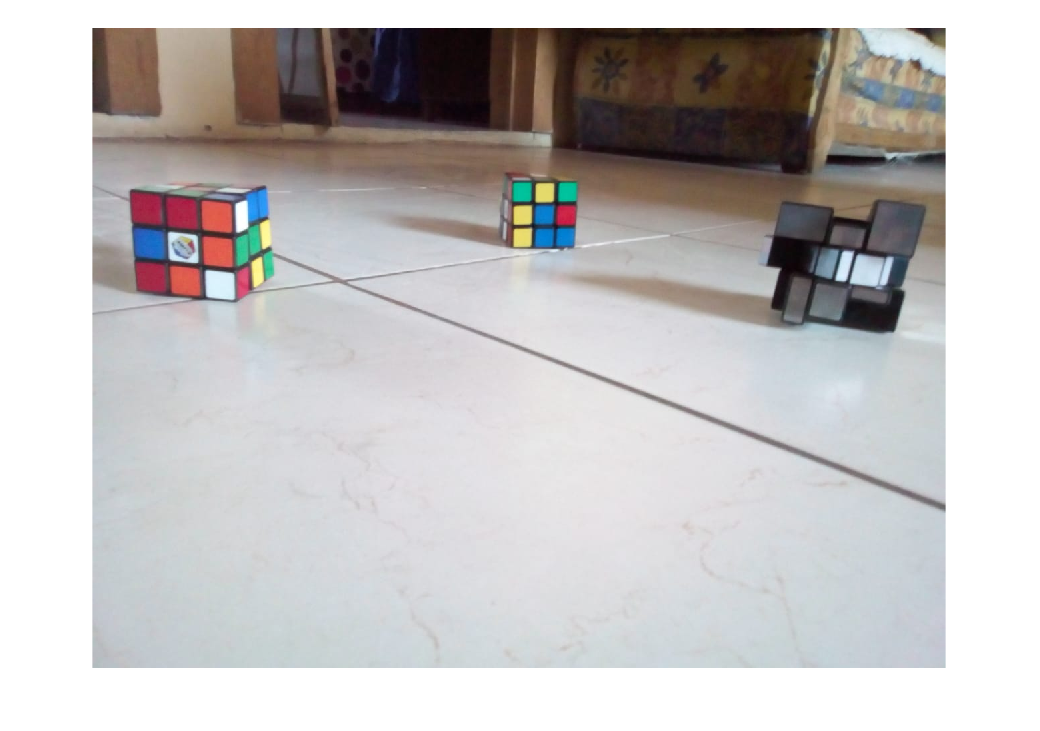

imOriginal = imread('im4.jpeg');
imshow(imOriginal)

Hacemos la conversión a escala de grises:

La conversión hace un promedio de los 3 colores de cada pixel.

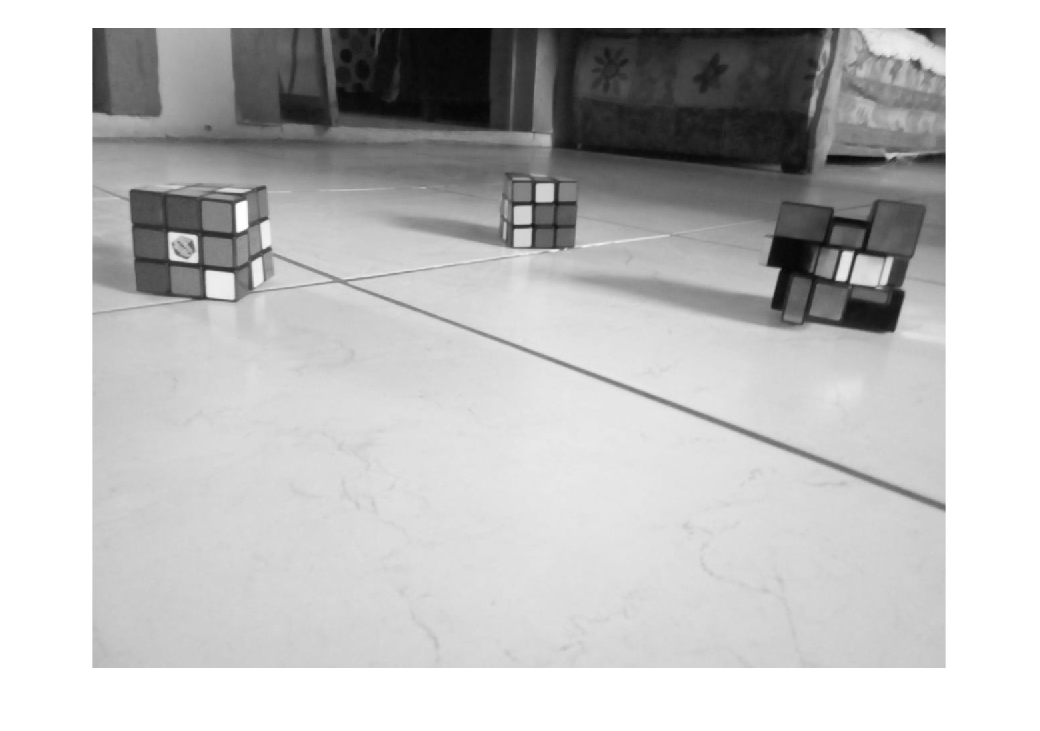

imGris = rgb2gray(imOriginal);
imshow(imGris)

Antes de disminuir el tamaño de la imagen conviene hacer un filtro para no perder parte de la información de la imagen, aplicaremos un filtro suavizador promedio para este efecto

**Filtro Promedio**

utilizamos el siguiente filtro:

h = ones(3)/9;

Realizamos la convolución de la imagen con el filtro para obtener la imagen con el filtro aplicado:

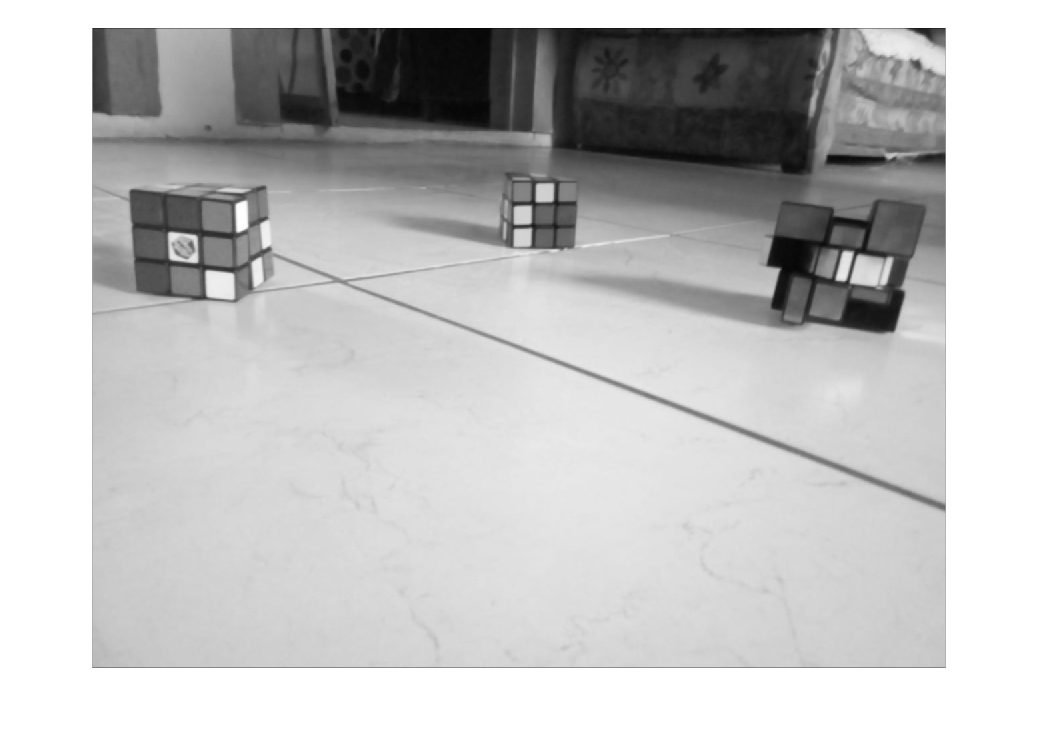

imFiltrada = uint8(conv2(imGris,h,'same'));
imshow(imFiltrada)

**Reducción de tamaño**

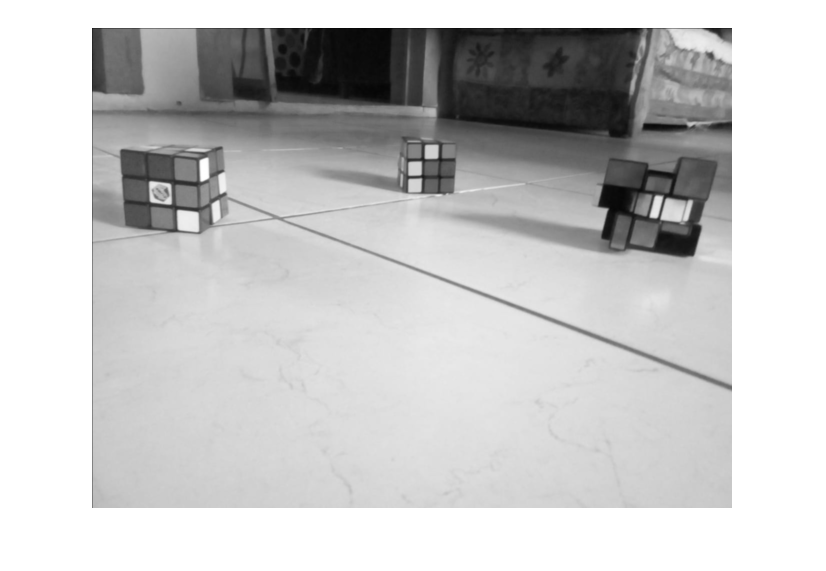

imReducida = imFiltrada(1:2:end,1:2:end);
imshow(imReducida)

**Aplicación de HDR a la imagen**

Para aplicar HDR es necesario hacer los siguientes pasos con la imagen en escala de grises:

- Calcular Histograma

- Normalizar la imagen

- Ecualizar la imagen

- Calcular HDR

Primero calculamos el histograma de la imagen:

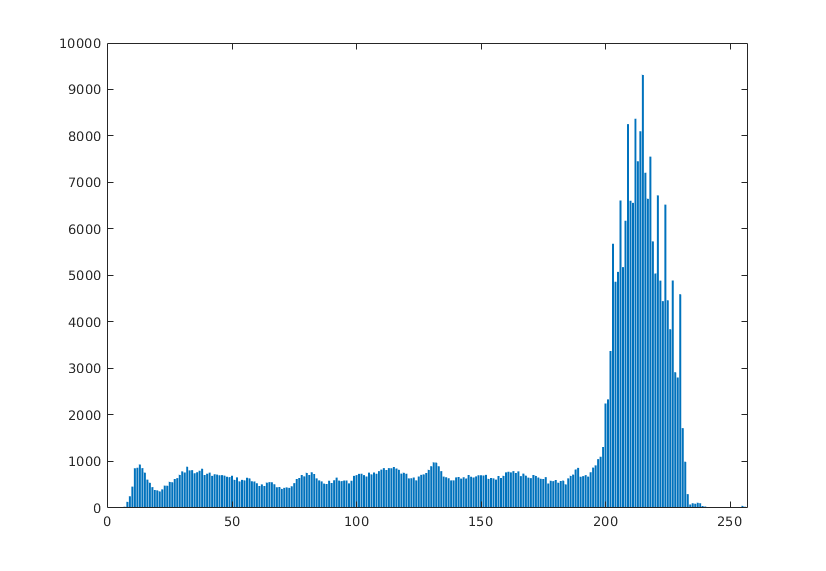

[histo,~]=imhist(imReducida);
bar(histo)

Hacemos un filtro rapido de altos y bajos tonos:

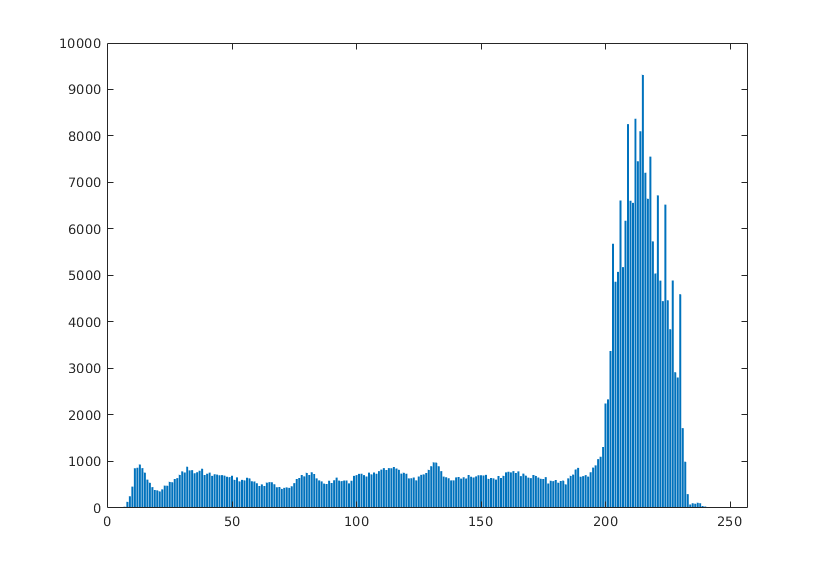

histo(1:5)=0;
histo(250:256)=0;
bar(histo)

Con la ayuda del histograma calculamos la frecuencia acumulada de la imagen:

histoAcum = zeros(1,256);
histoAcum(1)=histo(1);
for i=2:length(histo)
    histoAcum(i)=histoAcum(i-1)+histo(i);
end

Y despues con estos datos hacemos el histograma acumulado Normalizado

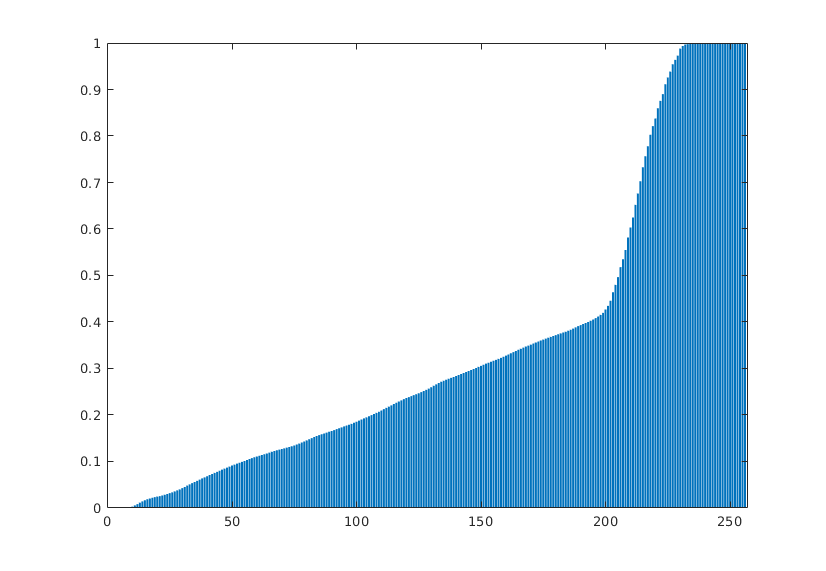

[r,c]=size(imReducida);
histoAcumNorma= histoAcum./(r*c);
bar(histoAcumNorma);

Una vez con el histograma acumulado normalizado, procedemos a ecualizar la imagen:

m = 255;
n = 0;
imEcualizada = zeros(r,c,'uint8');
for i = 1:r
    for j = 1:c
        imEcualizada(i,j)=uint8(histoAcumNorma(imReducida(i,j)+1)*m+n);
    end
end

%histograma final
histoEcualizado=zeros(1,256);
for i = 1:r
    for j = 1:c
        histoEcualizado(imEcualizada(i,j)+1) = histoEcualizado(imEcualizada(i,j)+1)+1;
    end
end


Con el código anterior obtenemos la imagen ecualizada:

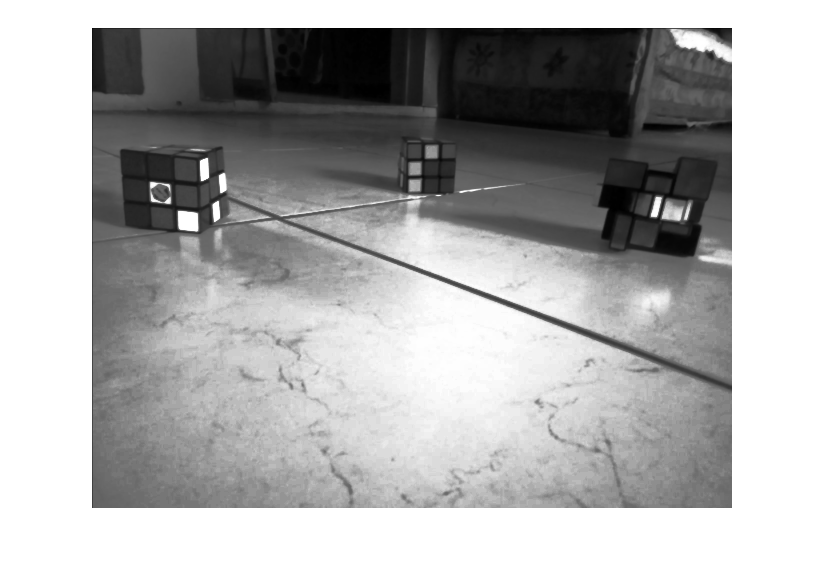

imshow(imEcualizada);

 y el histograma final:

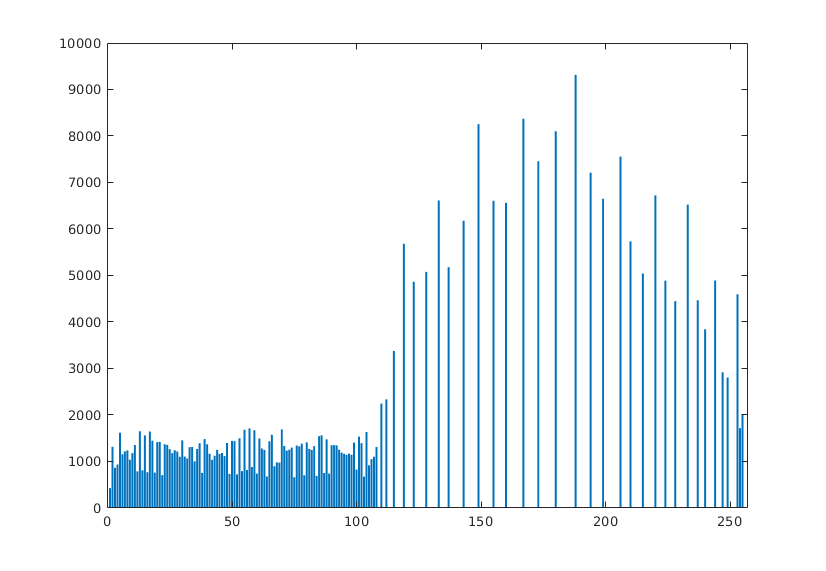

bar(histoEcualizado);

Por ultimo procedemos a calcular el HDR

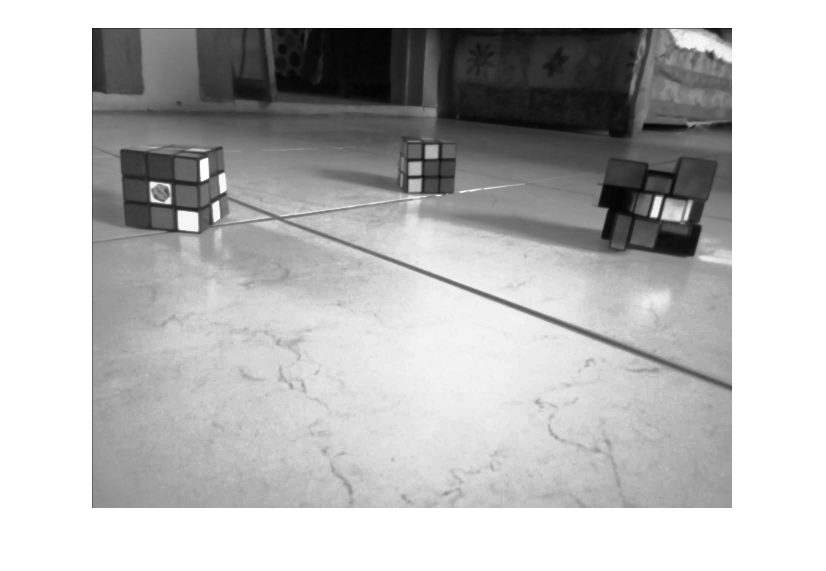

%HDR
imHDR = imReducida/2+imEcualizada/2;
imshow(imHDR);

## ***Filtro Mediana***

El filtro mediana nos ayudará a reducir el filtro de la imagen antes de hacer el calculo de Canny:

imMediana = zeros(r,c);
for i = 1:r
    for j = 1:c
        H = imHDR(max(i-1, 1):min(i+1,r), max(j-1, 1):min(j+1, c));
        imMediana(i,j) = median(median(H));
    end
end
imMediana = uint8(imMediana);

Obtenemos la imagen filtrada con reducción de ruido:

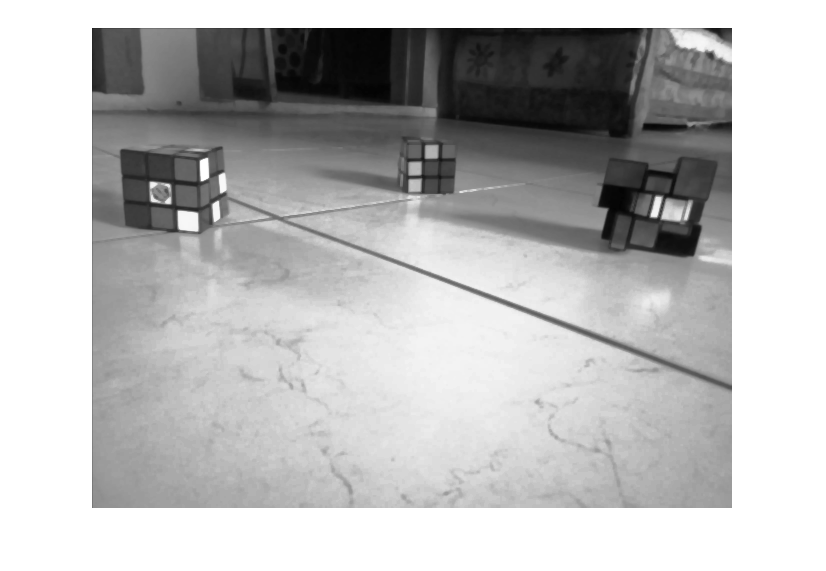

imshow(imMediana);

## ***Canny***

La aplicación del algoritmo Canny nos ayudará a obtener los bordes de la imagen, ya que la simple conversión de la imagen a blanco y negro no nos ayuda mucho a detectar objetos como podemos ver:

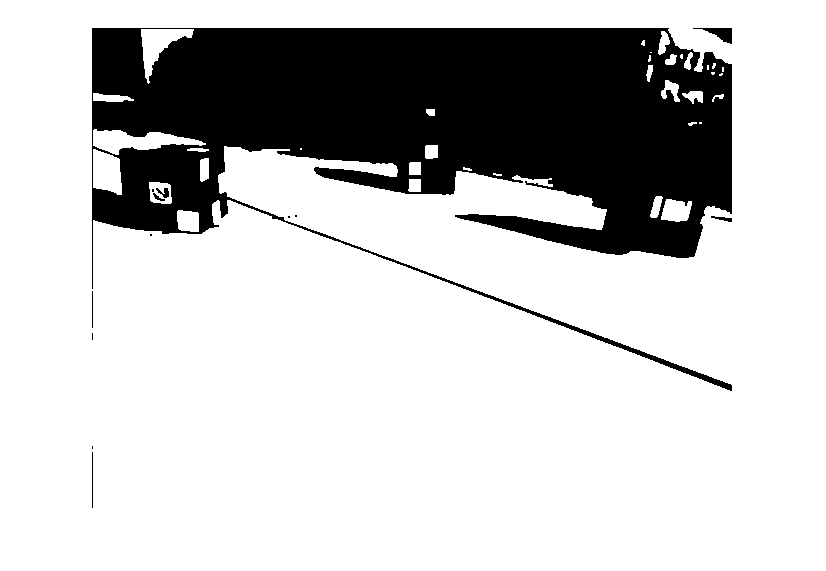

imMedianaBW=im2bw(imMediana,0.5);
imshow(imMedianaBW);

Para realizar el algoritmo Canny utilizaremos por practicidad para esta demostración el algoritmo de matlab, el cual aplica una derivada con el filtro de gauss y se le aplica un vector de dos posiciones con el cual se hace un umbral para la realización de histerisis.

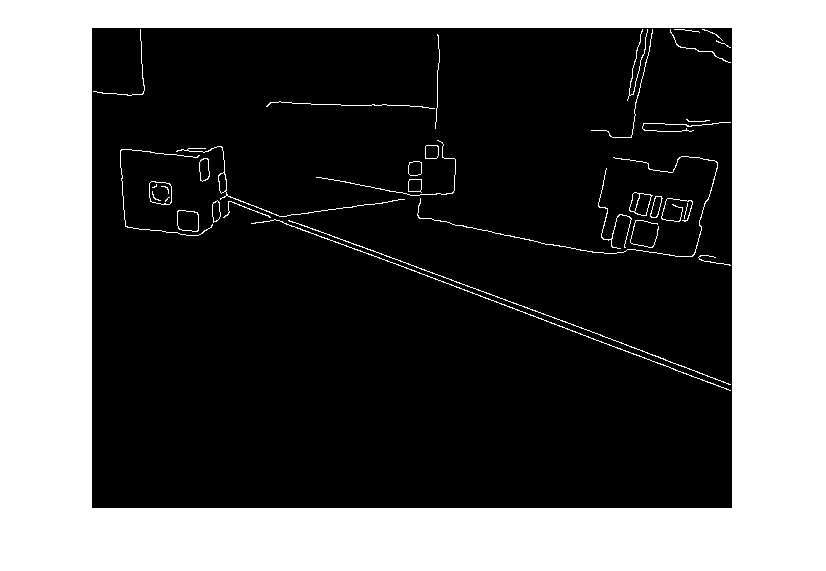

rangoHiste = [.1, 0.33];
imCanny=edge(imMediana,'Canny', rangoHiste);
imshow(imCanny);

## ***Closing a la imagen***

El siguiente paso es hacer un detallado de los bordes encontrados con el algoritmo Canny

Para ello se utiliza la operación closing, ya que le dimos un rango pequeño al Canny, los bordes pueden ser muy finos por lo cual conviene primero hacer dilatación de la imagen y despues erosión de la misma, y eso exactamente es lo que hace este algoritmo.

Se aplica la operación de Closing a la imagen con un filtro de cruz:

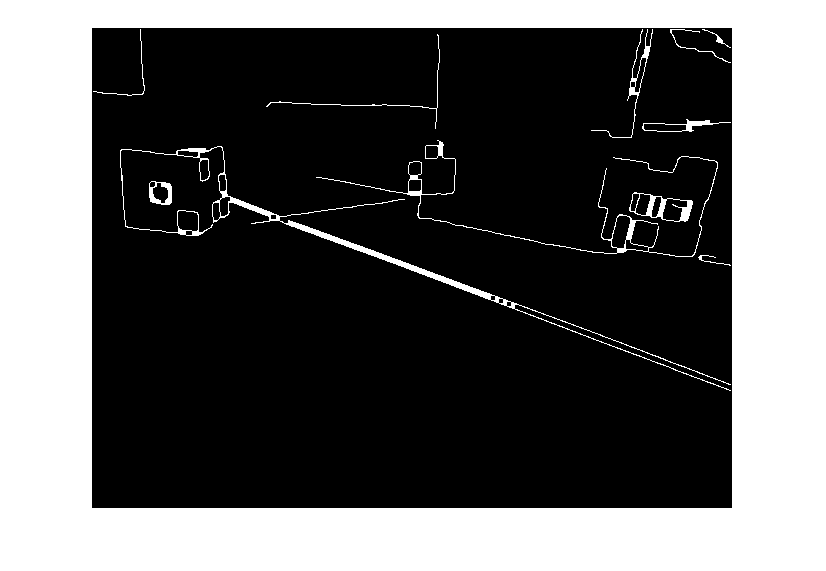

Se=[1 1 1 1 ;1 1 1 1 ;1 1 1 1;1 1 1 1];
imClosing = imclose(imCanny,Se);
imshow(imClosing);

Una vez realizado el closing de la imagen, toca realizar la erosión, que consiste en la eliminación de "detalles" que la imagen pueda tener, puntos innecesarios para el análisis de la imagen. Al tener la imagen de los bordes de los obstáculos en blanco y negro se le sustrae la erosión de la misma imagen con el filtro seleccionado y se agrega el resultado a una nueva imagen.

Para aplicar la erosión, se elige un filtro mas pequeño que elimina ruido horizontal o transversal, permitiendo encontrar las lineas verticales que seran los limites de los objetos a esquivar:

filtroErosion = [1 1 1 1];
imErosion=imerode(imClosing,filtroErosion);

Despues de realizar la erosión se restan las imagenes para encontrar los puntos de interes:

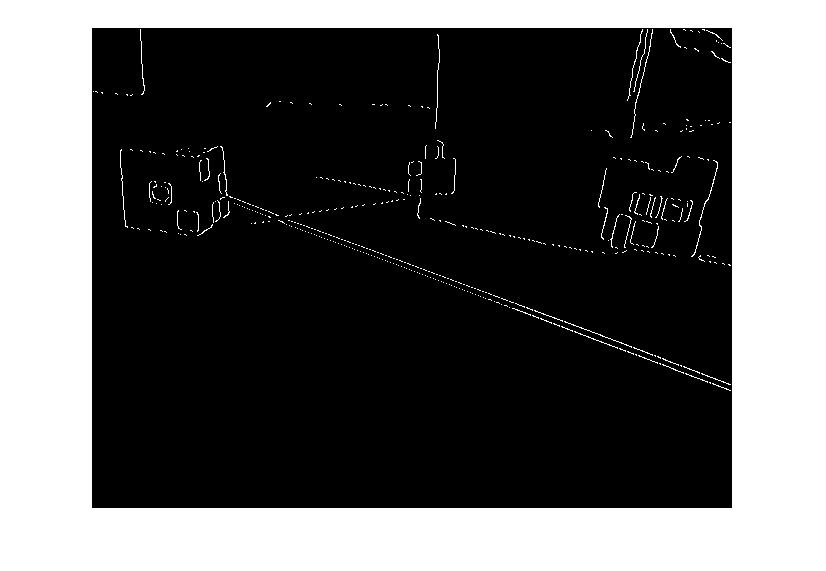

imBordes=imCanny-imErosion;
imshow(imBordes);

Despues de realizar la erosión quedan puntos solos que conviene quitar con un opening:

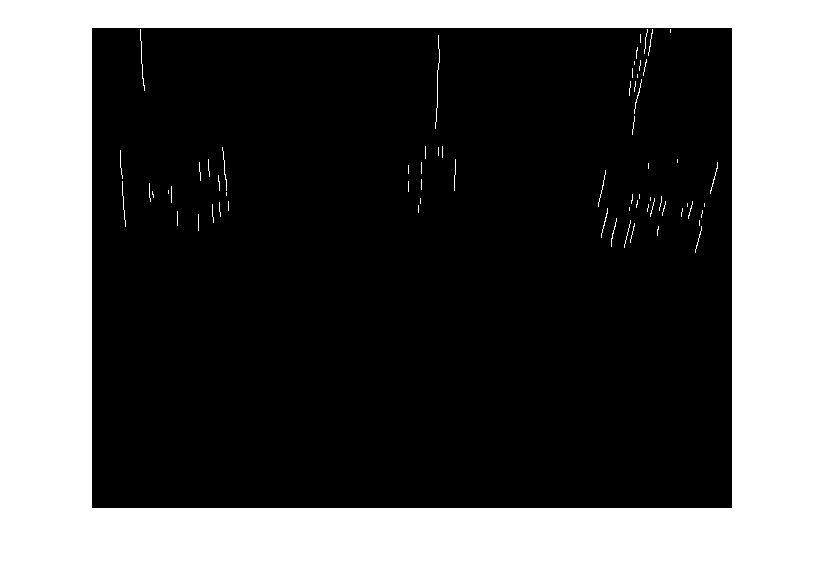

imOpen = imopen(imBordes,filtroErosion');
imshow(imOpen)

 La imagen final permite saber al robot los limites de los objetos que escaneará para esquivarlos con mayor facilidad.

## ***Detección de esquinas con Algoritmo Harris***

numEsquinas=100;
esquinas = corner(imOpen,'Harris', numEsquinas)

esquinas =     60   170
   134   168
   569   180
   557   181
   570   176
   581     1
   540    61
   539   197
   536   209
   537   205


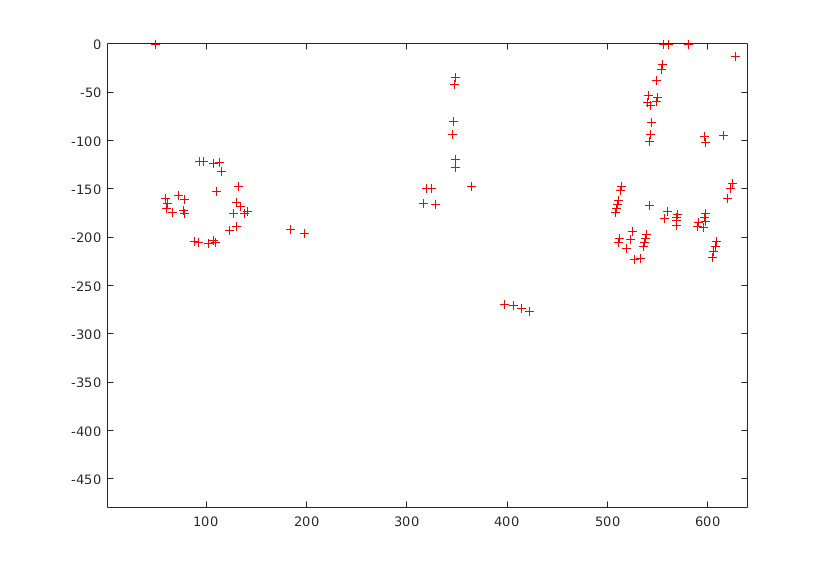

plot(esquinas(:,1),-esquinas(:,2),'r+');
axis([1 c -r 1])

Una vez obtenidas las coordenadas de las esquinas, se le puede pasar esta información facilmente al robot para que con un escaner de distancia simple como un sensor ultrasonico evalue la distancia a esa posición para esquivar el objeto.

Con la información de los puntos donde hay esquinas se pueden crear cuadrantes de 50 pixeles cada uno donde si no hay nada en ese cuadrante se descarta la revisión del sensor de proximidad en esa region.

numCasillas=50

numCasillas = 50

casillas =floor([c r]./numCasillas)+[1 1]

casillas =     13    10


votos = zeros(casillas);
votacion = floor(esquinas./numCasillas)

votacion =      1     3
     2     3
    11     3
    11     3
    11     3
    11     0
    10     1
    10     3
    10     4
    10     4


for i=1:numEsquinas
        votos(votacion(i,1)+1,votacion(i,2)+1)=votos(votacion(i,1)+1,votacion(i,2)+1)+1;
end
votos

votos =      1     0     0     0     0     0     0     0     0     0
     0     0     2     8     2     0     0     0     0     0
     0     0     4     8     3     0     0     0     0     0
     0     0     0     2     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     2     2     2     4     0     0     0     0     0     0
     0     0     1     0     0     1     0     0     0     0
     0     0     0     0     0     3     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


De esta forma podemos ver cuales tienen los mayores votos y solo 

[maxc, indexc] = max(votos)

maxc =      5     6     4    12     9     3     0     0     0     0


indexc =     12    11     3    12    11     9     1     1     1     1


[maxf, indexf] = max(maxc)

maxf = 12

indexf = 4

Con los index maximos podemos saber que el robot primero debe buscar en el cuadrante:

max1=[indexf, indexc(indexf)]

max1 =      4    12


Despues puede buscar el siguiente cuadrante:

votos(max1(2), max1(1))=0;
votos

votos =      1     0     0     0     0     0     0     0     0     0
     0     0     2     8     2     0     0     0     0     0
     0     0     4     8     3     0     0     0     0     0
     0     0     0     2     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     2     2     2     4     0     0     0     0     0     0
     0     0     1     0     0     1     0     0     0     0
     0     0     0     0     0     3     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


numMaximos = 5;
numMaximos = min([numMaximos, casillas(1)]);
indexMaximos = zeros(numMaximos,2);
for i=1:numMaximos
[maxc, indexc] = max(votos);
[~, indexf] = max(maxc);
indexMaximos(i,:)=[indexf, indexc(indexf)];
votos(indexMaximos(i,2), indexMaximos(i,1))=0;
end
indexMaximos

indexMaximos =      5    11
     4     2
     4     3
     4    11
     2    11


De esta manera podemos de ser necesario y si así lo quiere el usuario revisar con el escaner los maximos que se quieran para ver a que distancia se encuentran esos objetos. 